clear

tog.VOI = 'OcEnd-19';
tog.saveIt = 'yes';

par.fontSize = 14;                          %font size for plots
par.lineWidth = 4;                          %width of means polarplot line
par.smooth = 120;                            %number of windows to use for smoothing means

nbins = 21;


% C:\Users\510PAS\PhD\Data\NW_2019\' tog.VOI '.mat'

cd C:\Users\510PAS\PhD\Data\NW_2019\OcEnd
files = dir('*.mat');

lobData = cell(size(files));
for ii=1:length(files)
    aFileData = load(files(ii).name);
    lobData{ii} = aFileData; %.data;
end

## Broadband

for i=8 %:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = lobData{i,1}.BB;
    [mu,sigma,muCI,sigmaCI] = normfit(levels);
    x_pdf = floor(10*min(min(levels)))/10:0.1:ceil(10*max(max(levels)))/10;
    %x_pdf = linspace(min(levels(:,itime)),max(levels(:,itime)),length(what))
    ntimes = length(rads)
    nlevels = length(x_pdf)
    
    lobes = zeros(ntimes,nlevels);
    for itime = 1:ntimes
        lobes(itime,:) = normpdf(x_pdf,mu(itime),sigma(itime));
    end
end

ntimes = 1302

nlevels = 182

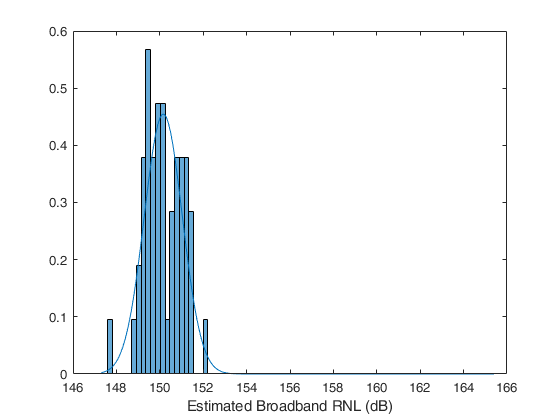


figure
histogram(levels(:,itime),nbins,'Normalization','pdf')
line(x_pdf,lobes(itime,:))
xlabel('Estimated Broadband RNL (dB)')

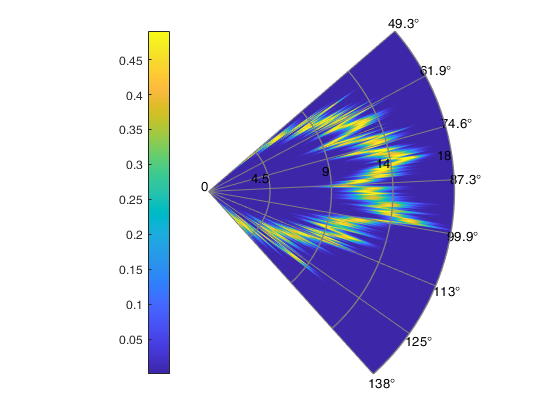


polarPcolor(x_pdf-x_pdf(1),rad2deg(rads),lobes);

## Engine tonal

for i=8 %:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(lobData{i,1}.tonal1.max',1,'gaussian',par.smooth);
    [mu,sigma,muCI,sigmaCI] = normfit(levels);
    x_pdf = floor(10*min(min(levels)))/10:0.1:ceil(10*max(max(levels)))/10;
    %x_pdf = linspace(min(levels(:,itime)),max(levels(:,itime)),length(what))
    ntimes = length(rads)
    nlevels = length(x_pdf)
    
    lobes = zeros(ntimes,nlevels);
    for itime = 1:ntimes
        lobes(itime,:) = normpdf(x_pdf,mu(itime),sigma(itime));
    end
end

ntimes = 1302

nlevels = 258

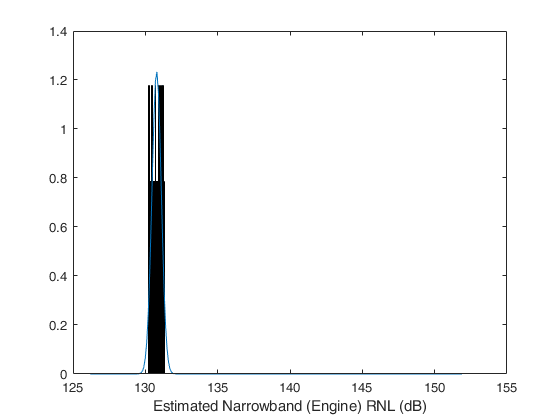


figure
histogram(levels(:,itime),nbins,'Normalization','pdf')
line(x_pdf,lobes(itime,:))
xlabel('Estimated Narrowband (Engine) RNL (dB)')

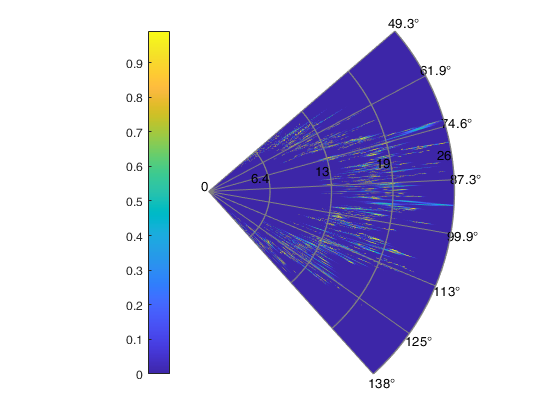


polarPcolor(x_pdf-x_pdf(1),rad2deg(rads),lobes);